# Basketball Players

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads, formats, and normalizes the data.

data = readtable("./data/bball.csv");
data.pos = categorical(data.pos);
stats = data{:, [5 6 11:end]};
labels = data.Properties.VariableNames([5 6 11:end]);
statsNorm = normalize(stats);

This code extracts the data for the guard position (`G`).

posStats = statsNorm(data.pos=="G", :);

## Task 1

Z = linkage(posStats, "ward");

gc2 = cluster(Z, "maxclust", 2);
gc3 = cluster(Z, "maxclust", 3);

This code visualizes the clusters.

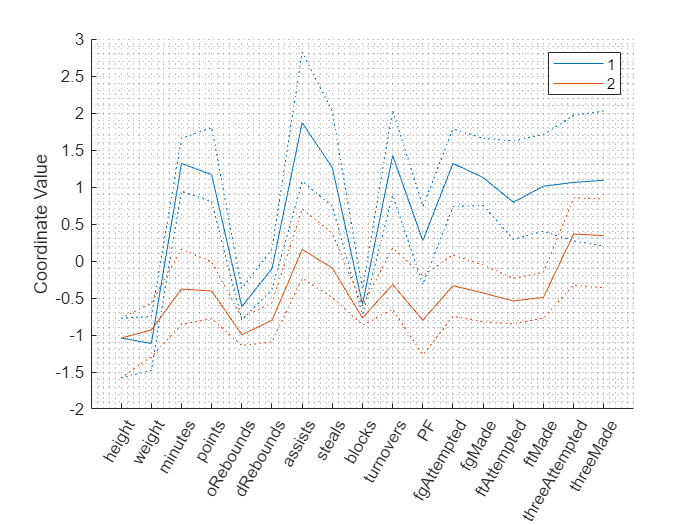

parallelcoords(posStats, "Group", gc2, "Quantile", 0.25, "Labels", labels)
grid minor
xtickangle(60)

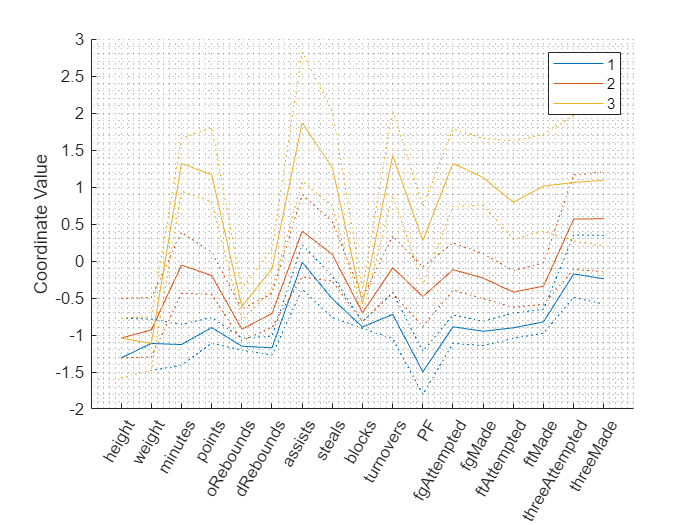

parallelcoords(posStats, "Group", gc3, "Quantile", 0.25, "Labels", labels)
grid minor
xtickangle(60)

## Task 2

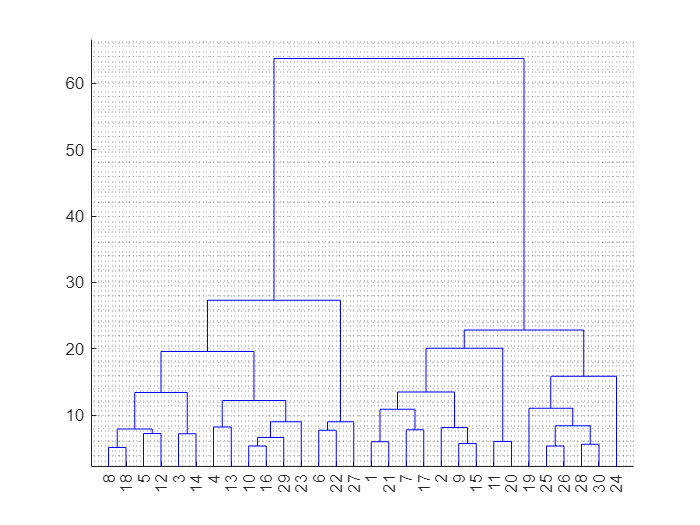

dendrogram(Z)
grid minor

ec = evalclusters(posStats, "linkage", "silhouette", "KList", 2:8)

ec =   SilhouetteEvaluation with properties:

    NumObservations: 367
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [0.5960 0.2794 0.2641 0.2348 0.2423 0.2516 0.2523]
           OptimalK: 2
